% インポート オプションの設定およびデータのインポート
opts = delimitedTextImportOptions("NumVariables", 9);

% 範囲と区切り記号の指定
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% 列名と型の指定
opts.VariableNames = ["tod", "ccmtype", "room", "region", "ord", "priority", "ip", "value", "id"];
opts.VariableTypes = ["datetime", "categorical", "double", "double", "double", "double", "categorical", "double", "double"];

% ファイル レベルのプロパティを指定
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 変数プロパティを指定
opts = setvaropts(opts, ["ccmtype", "ip"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "tod", "InputFormat", "yyyy-MM-dd HH:mm:ss");

% データのインポート
FLOWval = readtimetable("/home/horimoto/work/extract-pnr/FLOWval.csv", opts, "RowTimes", "tod");

% 一時変数のクリア
clear opts

% 結果の表示
FLOWval

FLOWval = 304×8 timetable
            tod            ccmtype     room    region    ord    priority         ip          value        id    
    ___________________    ________    ____    ______    ___    ________    _____________    _____    __________

    NaT                    ccmtype     NaN      NaN      NaN      NaN       ip                NaN            NaN
    2023-10-12 13:29:06    FLOW.mNB      0        0        0        1       192.168.120.5       0     7.3778e+08
    2023-10-13 09:13:00    FLOW.mNB      1        2       10        1       192.168.120.5       0     7.3972e+08
    2023-10-13 09:14:00    FLOW.mNB      1        2       10        1       192.168.120.5     0.8     7.3973e+08
    2023-10-13 09:14:00    FLOW.mNB      1        2       10        1       192.168.120.5     0.8     7.3973e+08
    2023-10-13 09:15:00    FLOW.mNB      1        2       10        1       192.168.120.5     1.1     7.3973e+08
    2023-10-13 09:15:00    FLOW.mNB      1        2       10        1

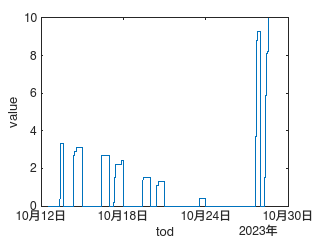

plot(FLOWval,"tod","value")